# **数学实验一**

### **1. 一步迭代算法及其收敛性**

#### 1.1.用Newton 选代法计算函数$f(x)=x^{5}+x+16$的正根，精度要求小数点后10位

-  设置初始猜测值、迭代终止条件、迭代次数上限：

x0 = 2;
tolerance = 1e-10;
maxIterations = 100;

- 用牛顿迭代法迭代，其迭代格式为$ x_{k+1}=x_{k} - \frac{f(x)}{  f^{\prime}(x)}$。

for i = 1:maxIterations
    % 计算函数和其导数
    fx = x0^5 + x0 - 16;
    fpx = 5 * x0^4 + 1;
    % 迭代
    x1 = x0 - fx / fpx;
    % 判断是否满足精度要求
    if abs(x1 - x0) < tolerance
        break;
    end
    % 更新迭代值
    x0 = x1;
end

if i == maxIterations
    disp('未能在指定的迭代步数内找到满足精度要求的解');
end

-  输出迭代次数与结果：

fprintf('使用Newton 选代法，经过 %d 次迭代，得到f(x)正根为 %.10f\n', i, x1);

使用Newton 选代法，经过 6 次迭代，得到f(x)正根为 1.7023656103


#### 1.2.自己构造一种一步迭代格式，先讨论其收敛性，必要的话将其改造为收敛选代格式，再用该选代格式重新计算函数$f(x)=x^{5}+x+16$的正根，精度要求小数点后10位，最后讨论改进算法以提高收敛速度/收敛阶。

- 构造迭代形式：$$x_{k+1}=\sqrt[5]{16-x_{k}}$$。

- 收敛性讨论：$$\phi(x)=\sqrt[5]{16-x}$$，$$\phi^{\prime}(x)=\frac{\sqrt[5]{16-x}}{5\,{\left(x-16\right)}}$$。

                运行下列代码，可见x0=2时，$|{\phi(2)|=0.0242<1$，所以该迭代格式收敛，且收敛阶为1。

clear;
% 定义函数
f = @(x) x.^5 + x - 16;
phi=@(x)nthroot(16-x, 5);
phi_1= @(x) nthroot(16 - x, 5)/(5*(x - 16));%求导数
disp('phi(2)=');

phi(2)=


disp(phi_1(2));

   -0.0242



- 设计程序，得到正根：

% 设置精度要求、初始值、最大迭代次数
tolerance = 1e-10;
maxIterations = 100;
x1 = 2;
% 迭代
for i = 1:maxIterations
    x2 =phi(x1);
    % 检查是否满足精度要求
    if abs(x2 - x1) < tolerance
        break;
    end
    % 更新迭代值
    x1 = x2;
end
%检查是否迭代成功
if i == maxIterations
    disp('未能在指定的迭代步数内找到满足精度要求的解');
end
%输出
fprintf('使用自己构造的一步迭代格式，经过 %d 次迭代，得到f(x)正根为 %.10f\n', i, x2);

使用自己构造的一步迭代格式，经过 7 次迭代，得到f(x)正根为 1.7023656103


- 利用松弛改进算法$x_{k+1}=x_k+\frac{1}{(1-\phi^{\prime}(x_k))(\phi(x_k)-x_k)}$以提高收敛阶和收敛速度，得到正根：

% 迭代
x1 = 2;
for i = 1:maxIterations
    x2 = x1+(1/(1-phi_1(x1)))*(phi(x1)-x1);
    % 检查是否满足精度要求
    if abs(x2 - x1) < tolerance
        break;
    end
    % 更新迭代值
    x1 = x2;
end
%检查是否迭代成功
if i == maxIterations
    disp('未能在指定的迭代步数内找到满足精度要求的解');
end
%输出
fprintf('使用经过松弛改进算法优化的一步迭代格式，经过 %d 次迭代，得到f(x)正根为 %.10f\n', i, x2);

使用经过松弛改进算法优化的一步迭代格式，经过 3 次迭代，得到f(x)正根为 1.7023656103


#### 1.3 用选代法解决带响应时间及回声因素的“悬崖高度”模型，精度耍求小数点后4位。

        设系数k=0.05，记录时间t=4s，响应时间t0=0.1s，石块下落的时间为t1 ，声音传回来的时间记为t2，得到非线性方程组模型：

 
$$F_{1}(h,t_{1},t_{2})=h-\frac{g}{k^2}(kt_{1}+e^{-kt_{1}}-1)=0$$


    
$$F_{1}(h,t_{1},t_{2})=h-v_{s}t_{2}=0$$



$$F_{1}(h,t_{1},t_{2})=t_{0}+t_{1}+t_{2}-t=0$$


        定义$x=(h,t_{1},t_{2})^T$，$F=(F_{1},F_{2},F_{3})^T$，构造迭代格式$x_{k+1}=x_{k}-F^{\prime}(x_{k})^{-1}F(x_{k})$。

- 设置参数：

clear;
k = 0.05;
t = 4;
t0= 0.1;
g = 9.8;
vs= 343;

- 求雅各比矩阵表达式：

syms h t1 t2;
F = [h-((g/(k^2))*(k*t1+exp(-k*t1)-1)); h-vs*t2;t0+t1+t2-t];%非线性方程组矩阵
X = [h; t1;t2];
J = jacobian(F, X);
disp(J);

$$\left(\begin{array}{ccc} 1 & 196\,{\mathrm{e}}^{-\frac{t_{1}}{20}}-196 & 0\\ 1 & 0 & -343\\ 0 & 1 & 1 \end{array}\right)$$

- 设置迭代初始值

x0=[50 1 1]';
F=[0 0 0]';
% 将x0分量用物理符号表示，更容易纠错
h=x0(1);
t1=x0(2);
t2=x0(3);
% 初始化
F(1)=h-(g/(k*k))*(k*t1+exp(-k*t1)-1);
F(2)=h-vs*t2;
F(3)=t0+t1+t2-t;

- 设计迭代程序并输出结果：

% 设置迭代终止条件、迭代步次数上限
tolerance = [1e-2;1e-4;1e-4];
maxIterations = 100;
% 迭代
for i = 1:maxIterations
    h=x0(1);t1=x0(2);t2=x0(3);
    F = [h-(g/(k*k))*(k*t1+exp(-k*t1)-1); h-vs*t2; t0+t1+t2-t];
    J_F=[1, (98*exp((-t1/20)))/5 - 98/5, 0; 1, 0, -343; 0, 1, 1];
    % 更新x1
    x1=x0-J_F\F;
    % 判断是否满足精度要求
    if (abs(x1(1) - x0(1)) < tolerance(1)) && (abs(x1(2) - x0(2)) < tolerance(2)) &&(abs(x1(3) - x0(3)) < tolerance(3))
        break;
    end
    % 更新x0
    x0 = x1;
end
%检查是否迭代成功
if i == maxIterations
    disp('未能在指定的迭代步数内找到满足精度要求的解');
end
%输出
fprintf('经过 %d 次迭代，得到的悬崖高度h为 %.6f m\n', i, x1(1));

经过 6 次迭代，得到的悬崖高度h为 63.611411 m


### **2.  层次分析法（注：这题后面好像出了一点错，仅供参考）**

#### 2.1.用MATLAB编写程序，计算n=3~50时的n阶随机一致性指标，编制 FI表格，并与T.L.Saaty的结果进行比较。

clear;

- 设置参数与初始化：

n_values = 3:50;
ri_values = zeros(size(n_values));

- 对于每个n值，计算其RI。（注：函数getRI见末尾附录）

for i = 1:length(n_values)
    n = n_values(i);
    RI= getRI(n);
    ri_values(i) = RI;
end
% 以表格形式输出
T = table(n_values', ri_values', 'VariableNames', {'n', 'RI'});
disp(T);    

    n       RI   
    __    _______

     3    0.47197
     4    0.82428
     5    0.97216
     6      1.214
     7     1.2534
     8     1.3223
     9     1.3455
    10     1.4396
    11     1.4293
    12     1.4383
    13     1.4658
    14     1.4782
    15     1.4833
    16     1.4813
    17     1.5117
    18     1.5143
    19     1.5286
    20     1.5383
    21     1.5326
    22     1.5466
    23     1.5486
    24     1.5612
    25     1.5545
    26     1.5651
    27     1.5648
    28     1.5758
    29     1.5754
    30     1.5734
    31     1.5869
    32       1.58
    33     1.5913
    34     1.5856
    35     1.5857
    36     1.6001
    37      1.592
    38     1.5986
    39     1.5944
    40     1.6016
    41     1.6053
    42     1.6007
    43     1.6052
    44     1.6066
    45     1.6021
    46     1.6094
    47     1.6077
    48      1.611
    49     1.6056
    50     1.6084



- 与T.L.Saaty的结果进行比较，可发现RI系数与T.L.Saaty的结果接近，并呈现相同的变化趋势。

        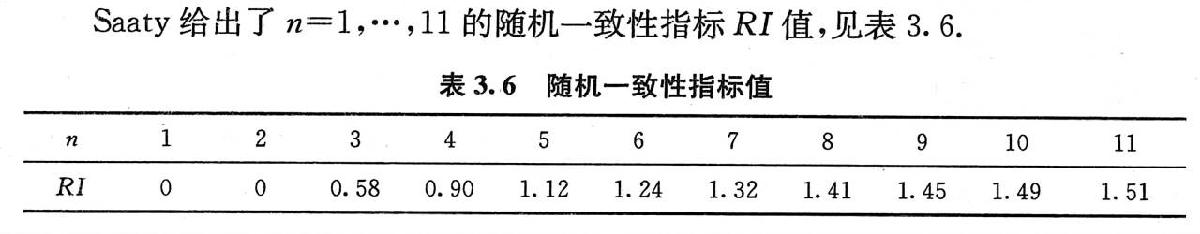

ri_saaty=[0.58,0.90,1.12,1.24,1.32,1.41,1.45,1.49,1.51];
e=zeros(1,length(ri_saaty));
for i=1:length(ri_saaty)
    e(i)=abs((ri_values(i)-ri_saaty(i))/ri_saaty(i));
end
disp('n从3到11时，RI的相对误差为');

n从3到11时，RI的相对误差为


disp(e);

    0.1863    0.0841    0.1320    0.0210    0.0505    0.0622    0.0721    0.0338    0.0535



#### 2.2b 请用AHP方法，选择合适的评价指标，从华为、小米、荣耀、苹果四个品牌手机中给出你对你心仪的下一款手机做出评价排序。

        选择指标有费用、性能、摄影功能、耐久度、生态。示意图如下：

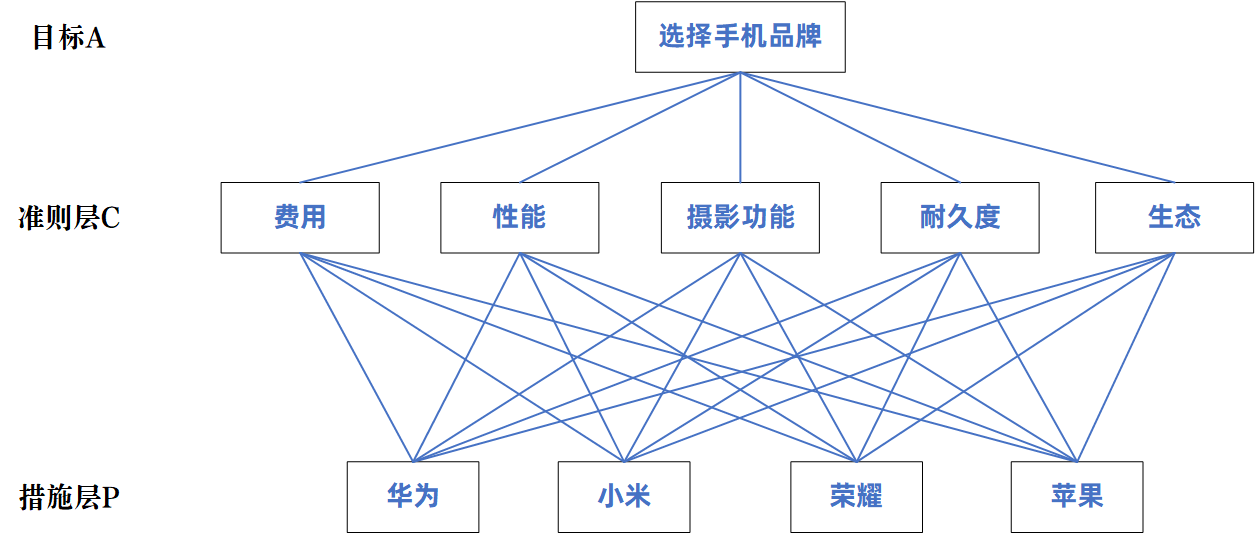

clear;

- 设置准则层权重矩阵：

A = [
    1     3     5     3     7;%费用
    1/3   1     2     1     5;%性能
    1/5   1/2   1     1/2   4;%摄影功能
    1/3   1     2     1     5;%耐久度
    1/7   1/5   1/4   1/5   1 %生态
    ];

- 进行一致性检验：

% 计算判定矩阵的特征值
eig_values = eig(A);
% 计算特征值的最大值
t = max(eig_values);
%计算相关参数
n=5;
CI = (t-n)/(n-1);
RI = [0 0 0.52 0.89 1.12 1.36 1.41 1.46 1.49 1.52 1.54 1.56 1.58 1.59];
CR = CI/RI(n);
if CR<0.10
    disp('此判断矩阵一致性可以接受！');
end

此判断矩阵一致性可以接受！


- 计算准则层权重向量：

% 计算并显示准则层权重向量
w = geomean(A);
disp('准则层权重向量为')

准则层权重向量为


disp(w);

    0.3165    0.7860    1.3797    0.7860    3.7070



- 设置措施层P矩阵：

VS = [
    3  5  5  5  4;%华为
    6  3  4  4  4;%小米
    4  3  3  4  3;%荣耀
    1  5  5  2  6 %苹果
    ];

- 计算并显示每个手机品牌对应准则层的加权平均值，结果依次对应华为、小米、荣耀、苹果：

% 计算每个手机品牌对应准则层的加权和
weighted_sum = VS * w';
% 计算每个手机品牌对应准则层的加权平均值
weighted_average = weighted_sum ./ sum(w);
% 显示每个手机品牌对应准则层的加权平均值
T = table(['华为';'小米';'荣耀';'苹果'], weighted_average, 'VariableNames', {'手机品牌', '对应准则层的加权平均值'});
disp(T);    

    手机品牌    对应准则层的加权平均值
    _______    __________________

     华为            4.3778      
     小米            3.9781      
     荣耀            3.1581      
     苹果            5.0119      



        经过比较，我给出的排序为：**苹果、华为、小米、荣耀。**

### 附录：

- 计算一致性指标RI的函数：

function ri = getRI(n)
mmax=150;
k=0;
for h=1:mmax
    % 生成随机的 n 阶判定矩阵
    trigger = randi([1, 2], n, n);
    random_matrix = zeros(n, n);

    for i = 1:n
        for j = 1:n
            if trigger(i, j) == 1
                % 如果随机数小于等于9，则选取1-9的自然数
                random_matrix(i, j) = randi([1, 9]);
            else
                % 否则选取1-9的倒数
                random_matrix(i, j) = 1 / randi([1, 9]);
            end
        end
    end

    random_matrix(logical(eye(n))) = 1; % 将对角线元素设置为1

    for i=1:n
        for j=1:i
            random_matrix(i,j) = 1/random_matrix(j,i); % 确保对称性
        end
    end
    
    % 计算判定矩阵的特征值
    eig_values = eig(random_matrix);
    % 计算特征值的最大值
    lambda_max = max(eig_values);
    % 累加
    k=k+lambda_max;
end
 % 取平均值
k=k/mmax;
% 计算一致性指标 RI
ri = (k - n) / (n - 1);
end